# **Lab 9**

### **Objective:**

The objective of this lab is to create a practical understanding of the Continuous time Fourier Series (Chapter 3 of textbook) and to prove various properties of the CTFS.

### **Theoretical Background:**

The Continuous Time Fourier Series is used for representation of continuous-time periodic signals:

CTFS representation of a periodic signal:        

Fourier Series Coefficients of a periodic signal:

### **Properties of the Continuous Time Fourier Series:**

There are many properties associated with the CTFS, in this lab the students will prove the following two properties, where:

- x(t) and y(t) are two continuous time periodic signals with period T and fundamental frequency   

-   and   are the Fourier Series Coefficients.

#### **Multiplication:**

- The Fourier Series representation of the product of two continuous time periodic signals x(t) and y(t) is equal to the convolution of their Fourier Series coefficients

#### **Differentiation:**

- The Fourier Series representation of differentiation of a periodic signal x(t) is equal to    –jw*(Fourier Series of x(t)).

### **Tasks:**

The following tasks are to be performed **individually** by each student:

#### **Task 1:**

Create separate functions in MATLAB for Continuous Time Fourier Series (CTFS), i.e. Fourier series coefficients of a signal and the Inverse Continuous Time Fourier Series (ICTFS), i.e. creating signal from Fourier Series Coefficients.

#### **Task 2:**

Using the functions for CTFS and ICTFS created in Task 1, prove the following properties (explained in theoretical background) of CTFS:

- Multiplication Property

- Differentiation Property

The specifications of the two signals should be:

- x(t) =  

- y(t) =  

- The signal period Tp=2*pi

- Number of coefficients k= -10 to 10

### Task 1 

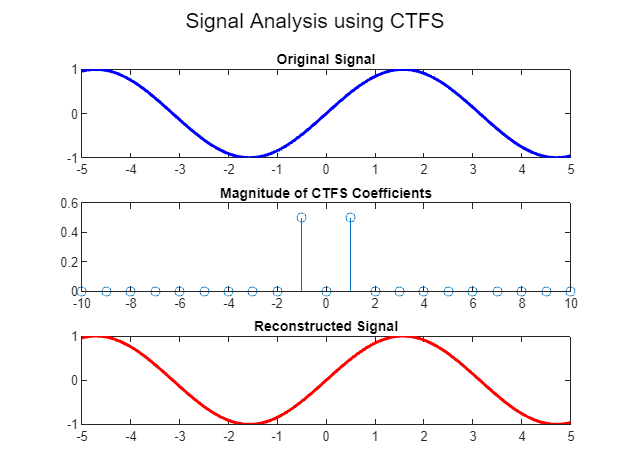

syms t ak;

T = 2*pi;
w = (2*pi)/T;
x = sin(t);
ak = CTFS(x, T);
x1 = ICTFS(ak, T);

figure;
subplot(3,1,1);
fplot(x, 'blue', 'linewidth', 2);
title('Original Signal');

subplot(3,1,2);
stem(-10:10, abs(ak));
title('Magnitude of CTFS Coefficients');

subplot(3,1,3);
fplot(x1, 'r', 'linewidth', 2);
title('Reconstructed Signal');

sgtitle('Signal Analysis using CTFS');

### Task 2 

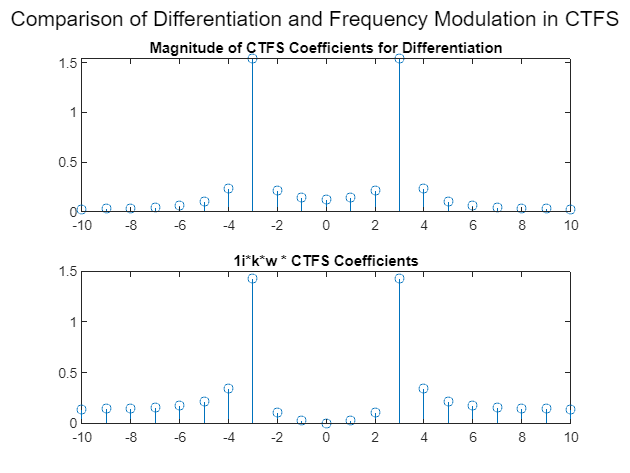

syms t;

x = sin(pi*t);
T = 2*pi;
k = -10:10;
w = (2*pi)/T;

Dif = diff(x, t);

figure;

LHS = CTFS(Dif, T);
subplot(2,1,1);
stem(k, abs(LHS));
title('Magnitude of CTFS Coefficients for Differentiation');

ak = CTFS(x, T);
RHS = (1i*k*w .* ak);
subplot(2,1,2);
stem(k, abs(RHS));
title('1i*k*w * CTFS Coefficients');

sgtitle('Comparison of Differentiation and Frequency Modulation in CTFS');

#### Function 1 

function ak = CTFS(x, T)
    syms t;
    w = (2*pi)/T;
    
    ak = zeros(1, 21);  % Initializing ak to zeros
    
    for k = -10:10
        ak(k+11) = (1/T) * int(x * exp(-1i*k*w*t), t, 0, T);
    end
end

#### Function 2 

function x = ICTFS(ak, T)
    syms t;
    w = (2*pi)/T;

    x = 0;
    for k = -10:10
        x = x + ak(k+11) * exp(1j*k*w*t);
    end
end